%dir_input = 'C:\Users\rsarin\Google Drive\ArmEMG\Data\SEEDS\FeaturesSubj\';
dir_input = 'C:\Users\saman\Google Drive\HAL\Projects\ArmEMG\Data\SEEDS\FeaturesSubj\';
fname_input = '-SEEDSfeatures'; %Tag for file name (follows subject name)
includedspeeds={'both','slow','fast'}; %cell array of all speeds
sp = 1 %speed we want to examine

sp = 1

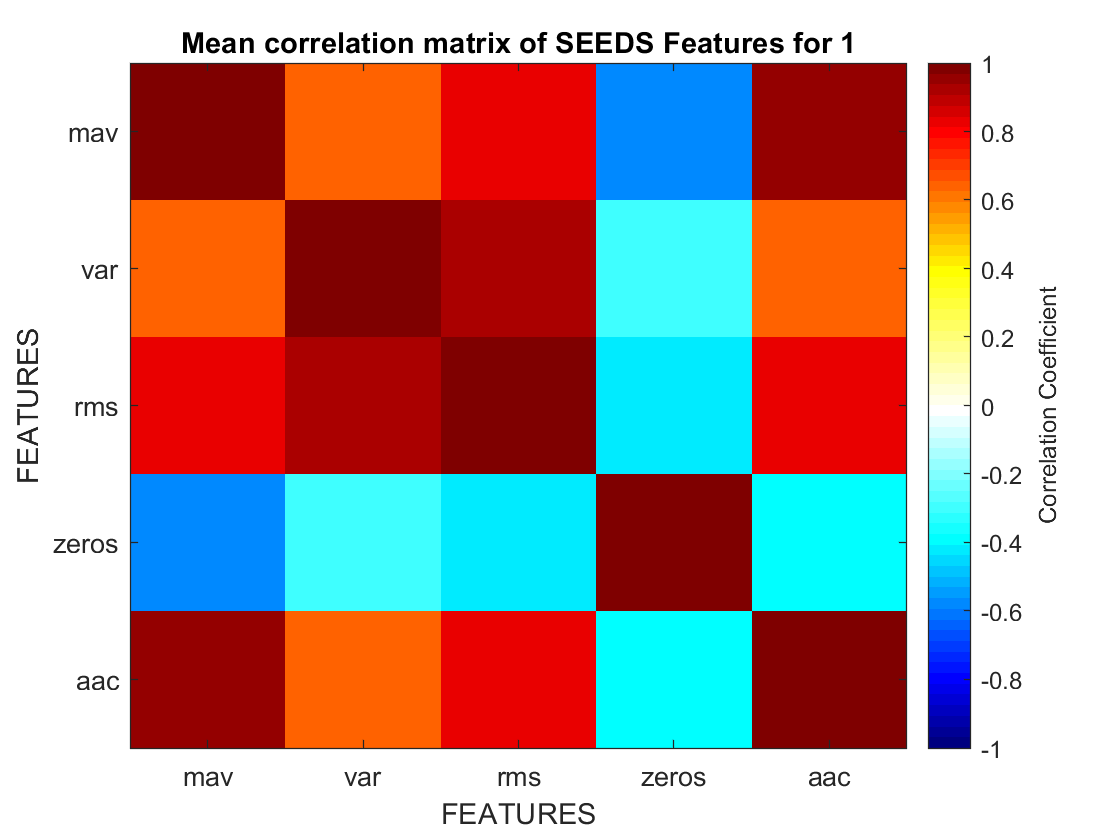

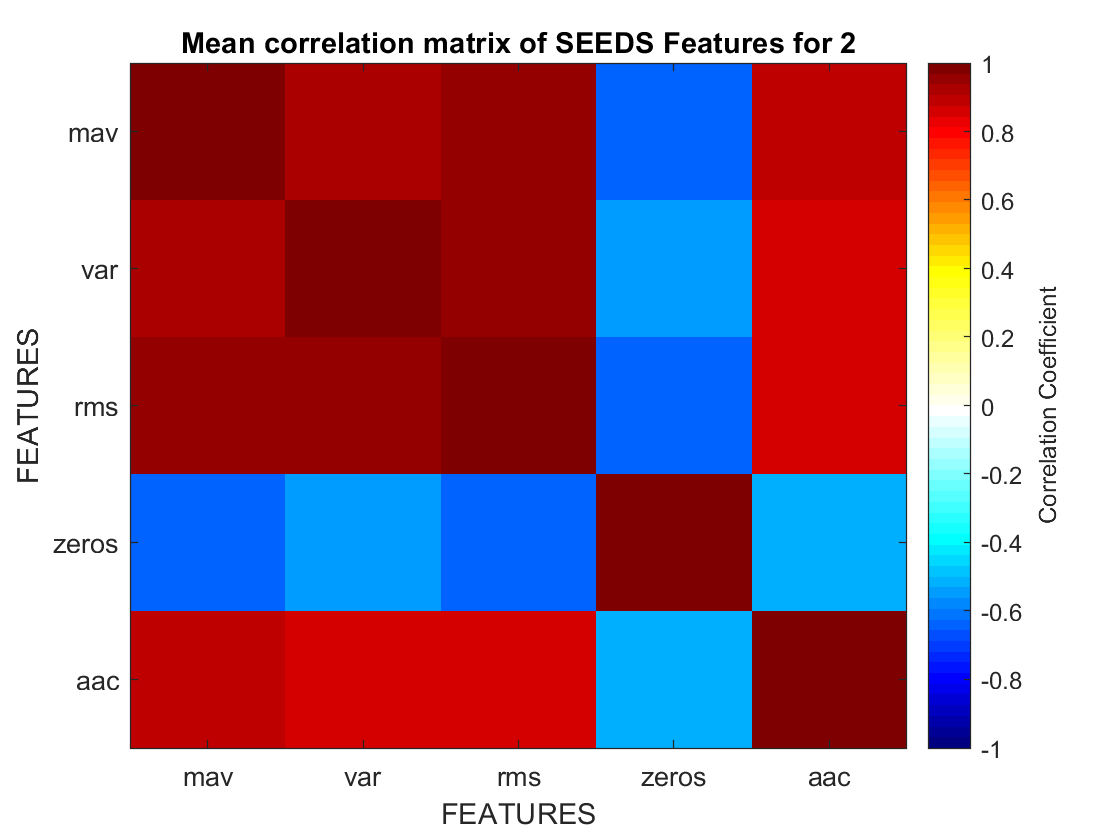

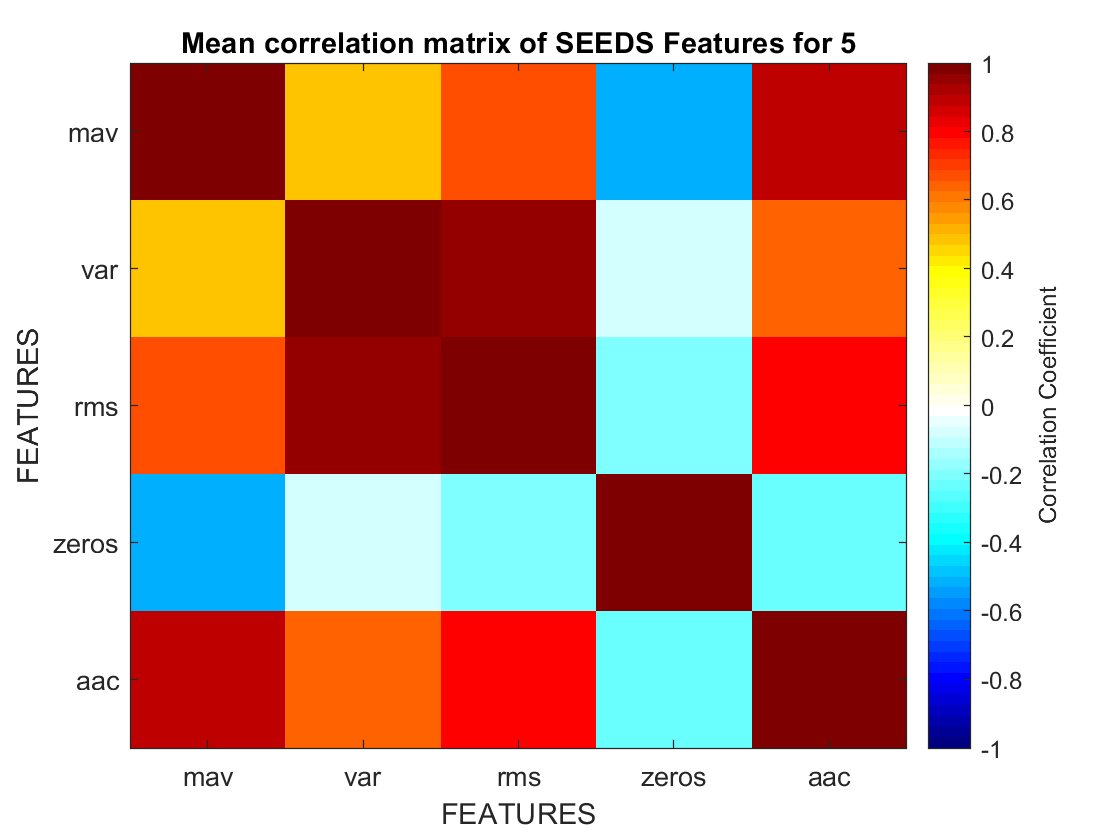

includedsubjectnumbers = [1 2 5]; %total number of subjects we will examine. This is a temporary fix. I want Matlab to calculate this.

for s = 1:length(includedsubjectnumbers) %iterate through each subject  
    load(strcat(dir_input,'subj',num2str(includedsubjectnumbers(s),'%02.f'),fname_input,'_speed',includedspeeds{sp},'.mat'),'traindata') %load data for the subject
    corr_mat(:,:,s) = featureCorrelationFunc(includedchannels, includedfeatures, traindata); %For each subject, call featureCorrelationFunc.m
    figure %to ensure we don't delete our old figure each time the loop runs
    plot_feat_corr(corr_mat(:,:,s),includedfeatures,includedsubjectnumbers(s)); %input subject number if you want this in the title
end

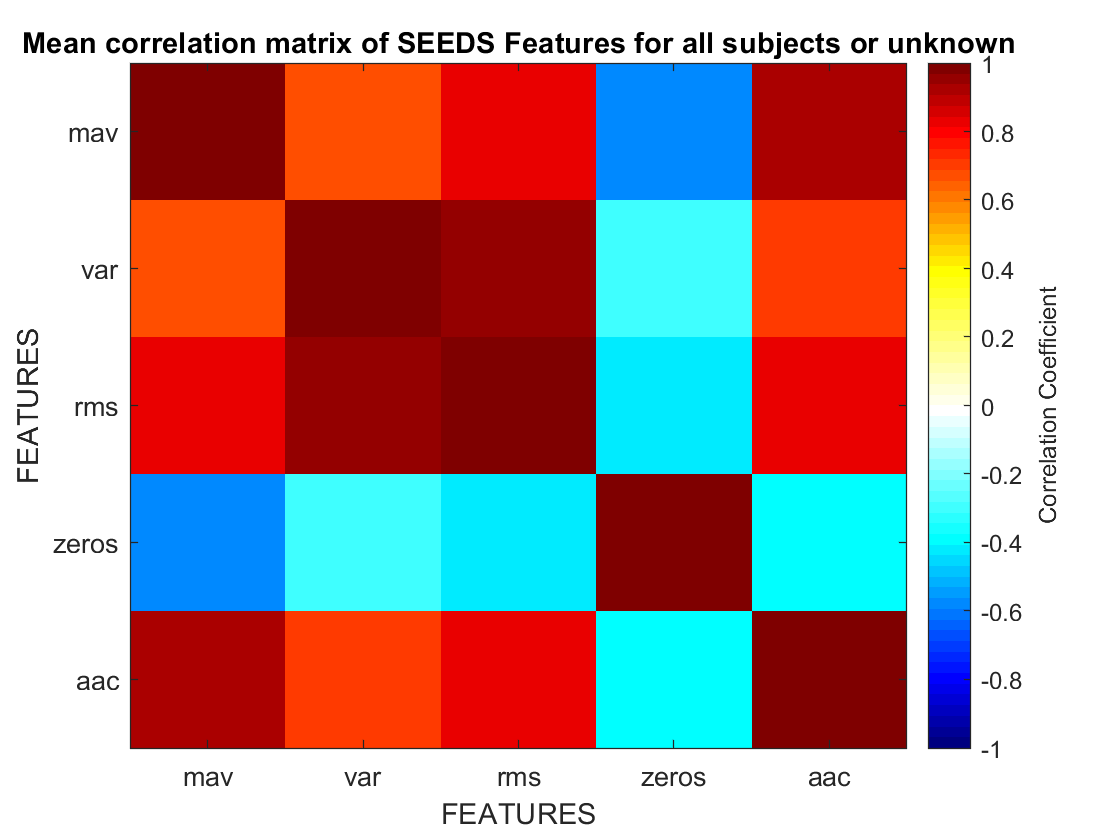

meansubjcorrmat = mean(corr_mat,3); %mean of corr coeffs for all features across channels measured (size = #features x #features x 1)
figure
plot_feat_corr(meansubjcorrmat,includedfeatures)